1. Brief Historical Background

Adaptive filtering is a major area of Digital Signal Processing (DSP) in which filter coefficients are updated automatically from measured data. Unlike fixed filters, adaptive filters are useful when the system, channel, or environment is unknown, time-varying, or affected by noise.

The Least Mean Squares (LMS) algorithm became widely used because it is simple, stable under suitable step-size conditions, and computationally practical for real-time DSP applications. LMS-type algorithms are commonly applied in channel estimation, adaptive equalization, echo cancellation, acoustic noise cancellation, and unknown system identification.

The unknown system is modeled as a second-order Butterworth low-pass filter. The adaptive FIR filters attempt to learn the input-output behavior of this unknown system.

2. Project Objective

The objective is to identify an unknown linear time-invariant (LTI) system using adaptive FIR filtering. The same input signal x(n) is applied to the unknown Butterworth system and to the adaptive FIR filter. The unknown system produces the desired signal d(n), while the adaptive filter produces the estimated signal y(n).

The error signal is:

e(n) = d(n) - y(n)

The adaptive algorithm uses e(n) to update the FIR coefficients until the adaptive filter output becomes close to the desired signal.

clc; clear; close all;

rng(7); N = 50000; % Number of samples 
M = 7; % Adaptive FIR filter length 
fs = 8000; % Sampling frequency 
mu_lms = 5e-2; % Step size for Standard LMS 
mu_sign = 5e-5; % Step size for Sign-LMS and Sign-Sign LMS 
noise_power = 0.001; 


3. Input Signal and Unknown Butterworth System

A white Gaussian input signal is used because it excites a broad range of frequencies. This makes it suitable for system identification.

The unknown system is a second-order Butterworth low-pass filter. A Butterworth filter is useful as a reference system because it has a smooth magnitude response in the passband.

The desired signal d(n) is obtained by filtering x(n) through the unknown system and adding measurement noise.


% Input excitation signal 
x = randn(N, 1); 
% Unknown LTI system 
[b_sys, a_sys] = butter(2, 0.25); 
d_clean = filter(b_sys, a_sys, x); 
% Desired signal with measurement noise 
d = d_clean + sqrt(noise_power) * randn(N, 1); 
% Run algorithms 
[y_lms, e_lms, W_lms] = run_lms_algorithm(x, d, M, mu_lms, "lms"); 
[y_slms, e_slms, W_slms] = run_lms_algorithm(x, d, M, mu_sign, "sign_lms"); 
[y_sslms, e_sslms, W_sslms] = run_lms_algorithm(x, d, M, mu_sign, "sign_sign_lms"); 
% Moving-average MSE 
window = 500; 
mse_lms = movmean(e_lms.^2, window); 
mse_slms = movmean(e_slms.^2, window); 
mse_sslms = movmean(e_sslms.^2, window);

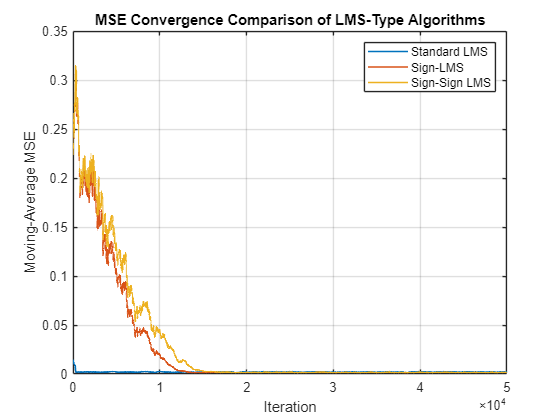

% Plot 1: MSE learning curves

figure; 
plot(mse_lms, 'LineWidth', 1.2); hold on; 
plot(mse_slms, 'LineWidth', 1.2); 
plot(mse_sslms, 'LineWidth', 1.2); 
grid on; 
xlabel('Iteration'); 
ylabel('Moving-Average MSE'); 
title('MSE Convergence Comparison of LMS-Type Algorithms'); 
legend('Standard LMS', 'Sign-LMS', 'Sign-Sign LMS');

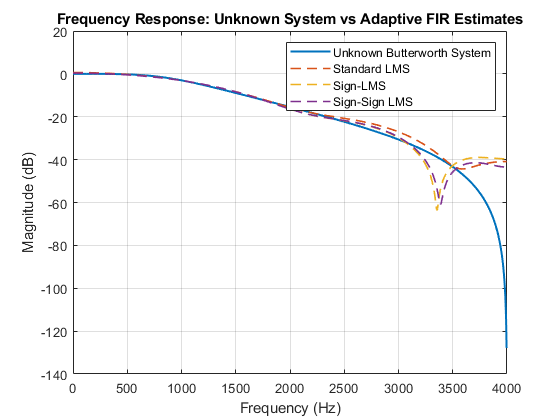

% Plot 2: Frequency response comparison

[H_sys, f] = freqz(b_sys, a_sys, 1024, fs);
[H_lms, ~] = freqz(W_lms(:, end), 1, 1024, fs);
[H_slms, ~] = freqz(W_slms(:, end), 1, 1024, fs);
[H_sslms, ~] = freqz(W_sslms(:, end), 1, 1024, fs);

figure;
plot(f, 20*log10(abs(H_sys) + 1e-12), 'LineWidth', 1.5); hold on;
plot(f, 20*log10(abs(H_lms) + 1e-12), '--', 'LineWidth', 1.2);
plot(f, 20*log10(abs(H_slms) + 1e-12), '--', 'LineWidth', 1.2);
plot(f, 20*log10(abs(H_sslms) + 1e-12), '--', 'LineWidth', 1.2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response: Unknown System vs Adaptive FIR Estimates');
legend('Unknown Butterworth System', 'Standard LMS', 'Sign-LMS', 'Sign-Sign LMS');

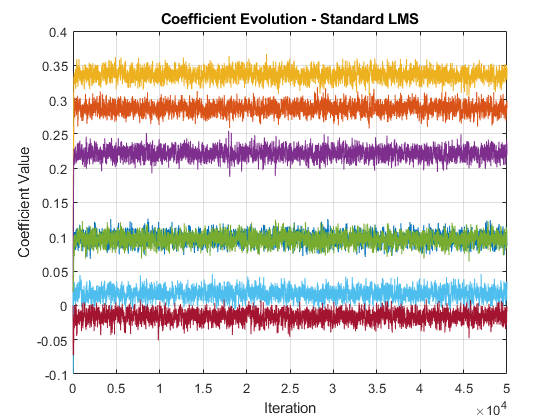

% ============================================================
% Plot 3: Coefficient evolution - Standard LMS
% ============================================================

figure;
plot(W_lms.');
grid on;
xlabel('Iteration');
ylabel('Coefficient Value');
title('Coefficient Evolution - Standard LMS');

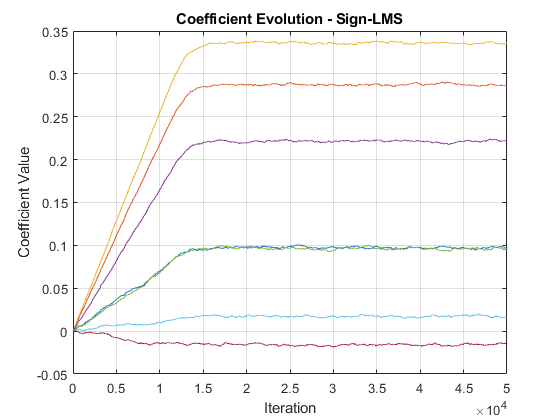

% ============================================================
% Plot 4: Coefficient evolution - Sign-LMS
% ============================================================

figure;
plot(W_slms.');
grid on;
xlabel('Iteration');
ylabel('Coefficient Value');
title('Coefficient Evolution - Sign-LMS');

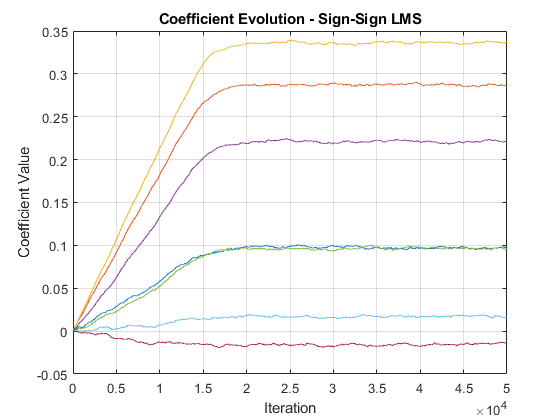

% ============================================================
% Plot 5: Coefficient evolution - Sign-Sign LMS
% ============================================================

figure;
plot(W_sslms.');
grid on;
xlabel('Iteration');
ylabel('Coefficient Value');
title('Coefficient Evolution - Sign-Sign LMS');

% ============================================================
% Numerical Summary
% ============================================================

fprintf('\nFinal Mean Squared Error Summary\n');


Final Mean Squared Error Summary


fprintf('----------------------------------\n');

----------------------------------


fprintf('Standard LMS     : %.6e\n', mean(e_lms(end-5000:end).^2));

Standard LMS     : 2.086385e-03


fprintf('Sign-LMS         : %.6e\n', mean(e_slms(end-5000:end).^2));

Sign-LMS         : 1.685338e-03


fprintf('Sign-Sign LMS    : %.6e\n', mean(e_sslms(end-5000:end).^2));

Sign-Sign LMS    : 1.687249e-03



fprintf('\nFinal Coefficients\n');


Final Coefficients


fprintf('----------------------------------\n');

----------------------------------


disp(table(W_lms(:,end), W_slms(:,end), W_sslms(:,end), ...
    'VariableNames', {'Standard_LMS','Sign_LMS','Sign_Sign_LMS'}));

    Standard_LMS    Sign_LMS     Sign_Sign_LMS
    ____________    _________    _____________

       0.087998      0.096754        0.0977   
        0.28828       0.28539         0.286   
        0.34484       0.33604        0.3367   
        0.22856       0.22265        0.2215   
        0.10746      0.095877        0.0967   
       0.024814      0.016382         0.016   
     -0.0076878     -0.014682       -0.0143   



% ============================================================
% Local function
% ============================================================


function [y, e, W_history] = run_lms_algorithm(x, d, M, mu, mode)

    N = length(x);
    w = zeros(M, 1);
    y = zeros(N, 1);
    e = zeros(N, 1);
    W_history = zeros(M, N);

    for n = M:N
        x_vec = x(n:-1:n-M+1);
        y(n) = w.' * x_vec;
        e(n) = d(n) - y(n);

        switch mode
            case "lms"
                w = w + mu * e(n) * x_vec;

            case "sign_lms"
                w = w + mu * sign(e(n)) * x_vec;

            case "sign_sign_lms"
                w = w + mu * sign(e(n)) * sign(x_vec);

            otherwise
                error("Unknown LMS mode.");
        end

        W_history(:, n) = w;
    end
end